# Electric Propulsion System - Fault Dataset Generator (Simscape Model)

This script generates healthy and faulty data using the actual Simscape model

Model: ElectricPropSys_digitalTwin.slx

**Faults Injected:**

  1. Battery: Increased internal resistance (0.05 → 0.15 Ω)

  2. Motor: Efficiency degradation (88% → 70%)

  3. Propeller: Blade damage - reduced thrust coefficient (Kt: 0.10 → 0.06)

clear; clc; 

## CONFIGURATION

% Simscape model name (without .slx extension)
model_name = 'ElectricPropSys_digitalTwin';

% Dataset parameters
num_simulations_per_class = 1000;   % Number of simulations per fault condition
simulation_time = 10;               % Seconds per simulation
sample_time = 0.01;                 % Sampling interval (100 Hz)

% Throttle variation range (for diverse operating conditions)
throttle_min = 0.3;
throttle_max = 1.0;

% Output filenames
output_csv = 'simscape_fault_dataset.csv';
output_mat = 'simscape_fault_dataset.mat';

## NOMINAL SYSTEM PARAMETERS (HEALTHY)

nominal = struct();

% Battery parameters
nominal.battery_voltage = 201.6;            % V
nominal.battery_resistance = 0.05;          % Ohm
nominal.battery_capacity = 100;             % Ah
nominal.battery_V1 = 180;                   % V (voltage at AH1)
nominal.battery_AH1 = 87;                   % Ah (charge at V1)

% Motor & Drive parameters
nominal.motor_max_torque = 100;             % N·m
nominal.motor_max_power = 20000;            % W
nominal.motor_efficiency = 88;              % %
nominal.motor_rated_speed = 2500;           % RPM
nominal.motor_rated_torque = 76;            % N·m
nominal.motor_time_constant = 0.015;        % s

% Propeller parameters (in MATLAB Function block)
nominal.prop_Kt = 0.10;                     % Thrust coefficient
nominal.prop_Kq = 0.060;                    % Torque coefficient
nominal.prop_diameter = 0.9;                % m
nominal.air_density = 1.225;                % kg/m³
nominal.prop_inertia = 0.05;                % kg·m²


## FAULT DEFINITIONS

faults = struct();

% Fault 0: Healthy (no fault)
faults(1).name = 'Healthy';
faults(1).label = 0;
faults(1).battery_resistance = nominal.battery_resistance;  % 0.05 Ω
faults(1).motor_efficiency = nominal.motor_efficiency;      % 88%
faults(1).prop_Kt = nominal.prop_Kt;                        % 0.10

% Fault 1: Battery degradation (increased internal resistance)
faults(2).name = 'Battery_Fault';
faults(2).label = 1;
faults(2).battery_resistance = 0.15;                        % 3x normal
faults(2).motor_efficiency = nominal.motor_efficiency;
faults(2).prop_Kt = nominal.prop_Kt;

% Fault 2: Motor efficiency degradation
faults(3).name = 'Motor_Fault';
faults(3).label = 2;
faults(3).battery_resistance = nominal.battery_resistance;
faults(3).motor_efficiency = 70;                            % Reduced from 88%
faults(3).prop_Kt = nominal.prop_Kt;

% Fault 3: Propeller damage (reduced thrust coefficient)
faults(4).name = 'Propeller_Fault';
faults(4).label = 3;
faults(4).battery_resistance = nominal.battery_resistance;
faults(4).motor_efficiency = nominal.motor_efficiency;
faults(4).prop_Kt = 0.06;                                   % Reduced from 0.10

## LOAD AND CONFIGURE SIMSCAPE MODEL

fprintf('  Simscape Fault Dataset Generator\n');

  Simscape Fault Dataset Generator


% Check if model exists
if ~exist([model_name, '.slx'], 'file')
    error('Model "%s.slx" not found in current directory. Please ensure the model is in the MATLAB path.', model_name);
end

% Load the model
fprintf('Loading Simscape model: %s.slx\n', model_name);

Loading Simscape model: ElectricPropSys_digitalTwin.slx


load_system(model_name);

% Set simulation parameters
set_param(model_name, 'StopTime', num2str(simulation_time));
set_param(model_name, 'Solver', 'ode23t');
set_param(model_name, 'MaxStep', '0.001');

fprintf('Model loaded successfully.\n\n');

Model loaded successfully.



## BLOCK PATH DEFINITIONS

% Update these paths to match your actual model structure

% Battery block path
battery_block = [model_name, '/Battery'];

% Motor & Drive block path
motor_block = [model_name, '/Motor & Drive'];

% Propeller MATLAB Function block path (for Kt parameter)
Kt_block = [model_name, '/Propeller_EPS/Kt'];

% Throttle/Torque input (constant) block path
throttle_block = [model_name, '/Throttle'];

## VERIFY BLOCK PATHS (with error handling)

fprintf('Verifying block paths...\n');

Verifying block paths...



% List of blocks to verify
blocks_to_verify = {
    battery_block, 'Battery';
    motor_block, 'Motor & Drive';
    throttle_block, 'Throttle';
    Kt_block, 'Kt'
};

% Check each block
for i = 1:size(blocks_to_verify, 1)
    block_path = blocks_to_verify{i, 1};
    block_name = blocks_to_verify{i, 2};
    
    try
        get_param(block_path, 'BlockType');
        fprintf('  ✓ %s block found\n', block_name);
    catch
        warning('  ✗ %s block not found at: %s', block_name, block_path);
        fprintf('    Please update the block path in the script.\n');
    end
end

  ✓ Battery block found
  ✓ Motor & Drive block found
  ✓ Throttle block found
  ✓ Kt block found


## DATASET GENERATION LOOP

% Initialize dataset storage
all_data = [];
all_labels = [];

% Column headers for dataset
feature_names = {'Fault Label', 'Throttle', 'Mean Voltage', 'Mean Current', 'Mean Speed_RPM', ...
                 'Mean Torque', 'Mean Thrust', 'Electrical Power', 'Mechanical Power', 'Efficiency'};

total_simulations = length(faults) * num_simulations_per_class;
sim_count = 0;
Kt_input = 0.1;

fprintf('Starting dataset generation...\n');

Starting dataset generation...


fprintf('Total simulations: %d\n\n', total_simulations);

Total simulations: 200



% Loop through each fault condition
for f = 1:length(faults)
    
    fault = faults(f);
    fprintf('Fault Condition: %s (Label: %d)\n', fault.name, fault.label);
    
    % Display fault parameters
    fprintf('Parameters:\n');
    fprintf('  Battery R: %.3f Ω\n', fault.battery_resistance);
    fprintf('  Motor η: %.0f%%\n', fault.motor_efficiency);
    fprintf('  Prop Kt: %.3f\n', fault.prop_Kt);
    fprintf('\n');
    
    %% Set fault parameters in model
    
    % 1. Set Battery internal resistance
    try
        set_param(battery_block, 'R1', num2str(faults(f).battery_resistance));
        fprintf('  Set Battery R = %.3f Ω\n', faults(f).battery_resistance);
    catch ME
        warning('Could not set Battery resistance: %s',f, ME.message);
    end
    
    % 2. Set Motor & Drive efficiency
    try
        set_param(motor_block, 'eff', num2str(faults(f).motor_efficiency));
        fprintf('  Set Motor efficiency = %.0f%%\n', faults(f).motor_efficiency);
    catch ME
        warning('Could not set Motor efficiency: %s', f, ME.message);
    end
    
    % 3. Set Propeller Kt (in Constant Block Kt_block)
     try
        Kt_input = faults(f).prop_Kt;
        fprintf('  Set Propeller Kt = %.3f \n', faults(f).prop_Kt);
    catch ME
        warning('Could not set Propeller Kt: %s', f, ME.message);
     end
    
    %% Run multiple simulations with varying throttle
    for sim_idx = 1:num_simulations_per_class
        sim_count = sim_count + 1;
        
        % Random throttle for this simulation (creates diverse data)
        throttle = throttle_min + (throttle_max - throttle_min) * rand();
        
        % Set throttle in model
        set_param(throttle_block, 'Value', num2str(throttle * nominal.motor_max_torque));
        
        % Run simulation
        try
            fprintf('  Running simulation %d/%d (Throttle: %.1f%%)...', ...
                    sim_idx, num_simulations_per_class, throttle*100);
            
            simOut = sim(model_name, ...
                'SimulationMode', 'normal', ...
                'SaveOutput', 'on', ...
                'OutputSaveName', 'yout', ...
                'SaveTime', 'on', ...
                'TimeSaveName', 'tout');
            
            fprintf(' Done.\n');
            
        catch ME
            fprintf(' FAILED: %s\n', ME.message);
            continue;
        end
        
        %% Extract logged signals
        
        % Get time vector
        t = simOut.tout;
        
        % Get logged signals (adjust based on your model's logging setup)
        try
            voltage = simOut.V_battery.Data;
            current = simOut.I_battery.Data;
            speed_rads = simOut.omega.Data;
            torque = simOut.torque.Data;
            thrust = simOut.thrust.Data;
        catch
            warning('Could not extract signals. Check model logging configuration.');
            continue;
        end
        
        %% Calculate statistical features
        V_mean = mean(voltage);
        I_mean = mean(current);
        W_mean = mean(speed_rads);
        torque_mean = mean(torque);
        thrust_mean = mean(thrust);

        %% Calculate derived quantities
        num_samples = length(t);
        
        % Convert speed to RPM
        speed_rpm = W_mean * 9.549;
        
        % Calculate powers
        power_elec = V_mean .* I_mean;
        power_mech = abs(torque_mean) .* abs(W_mean);
        
        % Calculate efficiency (avoid division by zero)
        efficiency = power_mech/power_elec * 100;
        
        % Throttle column (constant for this simulation)
        throttle_col = throttle;
        
        %% Store data
        
        % Combine into data matrix
        sim_data = [faults(f).label, throttle_col, V_mean, I_mean, speed_rpm, ...
                    torque_mean, thrust_mean, power_elec, power_mech, efficiency];
        
        % Append to dataset
        all_data = [all_data; sim_data];
        
    end
    
    fprintf('Completed %s: %d simulations\n\n', faults(f).name, num_simulations_per_class);
end

Fault Condition: Healthy (Label: 0)


Parameters:


  Battery R: 0.050 Ω


  Motor η: 88%


  Prop Kt: 0.100


  Set Battery R = 0.050 Ω


  Set Motor efficiency = 88%


  Set Propeller Kt = 0.100 


  Running simulation 1/50 (Throttle: 81.1%)...

 Done.


  Running simulation 2/50 (Throttle: 82.2%)...

 Done.


  Running simulation 3/50 (Throttle: 74.4%)...

 Done.


  Running simulation 4/50 (Throttle: 33.2%)...

 Done.


  Running simulation 5/50 (Throttle: 56.9%)...

 Done.


  Running simulation 6/50 (Throttle: 95.2%)...

 Done.


  Running simulation 7/50 (Throttle: 53.6%)...

 Done.


  Running simulation 8/50 (Throttle: 71.1%)...

 Done.


  Running simulation 9/50 (Throttle: 32.6%)...

 Done.


  Running simulation 10/50 (Throttle: 99.9%)...

 Done.


  Running simulation 11/50 (Throttle: 39.6%)...

 Done.


  Running simulation 12/50 (Throttle: 61.3%)...

 Done.


  Running simulation 13/50 (Throttle: 49.1%)...

 Done.


  Running simulation 14/50 (Throttle: 47.1%)...

 Done.


  Running simulation 15/50 (Throttle: 37.2%)...

 Done.


  Running simulation 16/50 (Throttle: 86.0%)...

 Done.


  Running simulation 17/50 (Throttle: 32.3%)...

 Done.


  Running simulation 18/50 (Throttle: 90.5%)...

 Done.


  Running simulation 19/50 (Throttle: 58.9%)...

 Done.


  Running simulation 20/50 (Throttle: 48.2%)...

 Done.


  Running simulation 21/50 (Throttle: 71.9%)...

 Done.


  Running simulation 22/50 (Throttle: 99.3%)...

 Done.


  Running simulation 23/50 (Throttle: 51.5%)...

 Done.


  Running simulation 24/50 (Throttle: 32.4%)...

 Done.


  Running simulation 25/50 (Throttle: 90.6%)...

 Done.


  Running simulation 26/50 (Throttle: 44.0%)...

 Done.


  Running simulation 27/50 (Throttle: 84.1%)...

 Done.


  Running simulation 28/50 (Throttle: 31.4%)...

 Done.


  Running simulation 29/50 (Throttle: 96.7%)...

 Done.


  Running simulation 30/50 (Throttle: 56.5%)...

 Done.


  Running simulation 31/50 (Throttle: 53.5%)...

 Done.


  Running simulation 32/50 (Throttle: 65.7%)...

 Done.


  Running simulation 33/50 (Throttle: 89.3%)...

 Done.


  Running simulation 34/50 (Throttle: 55.0%)...

 Done.


  Running simulation 35/50 (Throttle: 35.6%)...

 Done.


  Running simulation 36/50 (Throttle: 32.8%)...

 Done.


  Running simulation 37/50 (Throttle: 68.4%)...

 Done.


  Running simulation 38/50 (Throttle: 81.1%)...

 Done.


  Running simulation 39/50 (Throttle: 69.1%)...

 Done.


  Running simulation 40/50 (Throttle: 46.7%)...

 Done.


  Running simulation 41/50 (Throttle: 30.6%)...

 Done.


  Running simulation 42/50 (Throttle: 89.8%)...

 Done.


  Running simulation 43/50 (Throttle: 70.3%)...

 Done.


  Running simulation 44/50 (Throttle: 61.3%)...

 Done.


  Running simulation 45/50 (Throttle: 35.8%)...

 Done.


  Running simulation 46/50 (Throttle: 99.4%)...

 Done.


  Running simulation 47/50 (Throttle: 63.0%)...

 Done.


  Running simulation 48/50 (Throttle: 61.4%)...

 Done.


  Running simulation 49/50 (Throttle: 84.3%)...

 Done.


  Running simulation 50/50 (Throttle: 79.0%)...

 Done.


Completed Healthy: 50 simulations



Fault Condition: Battery_Fault (Label: 1)


Parameters:


  Battery R: 0.150 Ω


  Motor η: 88%


  Prop Kt: 0.100


  Set Battery R = 0.150 Ω


  Set Motor efficiency = 88%


  Set Propeller Kt = 0.100 


  Running simulation 1

 Done.


  Running simulation 2/50 (Throttle: 83.5%)...

 Done.


  Running simulation 3/50 (Throttle: 74.3%)...

 Done.


  Running simulation 4/50 (Throttle: 40.9%)...

 Done.


  Running simulation 5/50 (Throttle: 86.4%)...

 Done.


  Running simulation 6/50 (Throttle: 84.9%)...

 Done.


  Running simulation 7/50 (Throttle: 30.4%)...

 Done.


  Running simulation 8/50 (Throttle: 63.8%)...

 Done.


  Running simulation 9/50 (Throttle: 81.5%)...

 Done.


  Running simulation 10/50 (Throttle: 76.6%)...

 Done.


  Running simulation 11/50 (Throttle: 33.7%)...

 Done.


  Running simulation 12/50 (Throttle: 93.7%)...

 Done.


  Running simulation 13/50 (Throttle: 91.1%)...

 Done.


  Running simulation 14/50 (Throttle: 42.0%)...

 Done.


  Running simulation 15/50 (Throttle: 38.2%)...

 Done.


  Running simulation 16/50 (Throttle: 58.2%)...

 Done.


  Running simulation 17/50 (Throttle: 52.3%)...

 Done.


  Running simulation 18/50 (Throttle: 99.0%)...

 Done.


  Running simulation 19/50 (Throttle: 93.3%)...

 Done.


  Running simulation 20/50 (Throttle: 88.5%)...

 Done.


  Running simulation 21/50 (Throttle: 96.1%)...

 Done.


  Running simulation 22/50 (Throttle: 34.8%)...

 Done.


  Running simulation 23/50 (Throttle: 37.6%)...

 Done.


  Running simulation 24/50 (Throttle: 53.6%)...

 Done.


  Running simulation 25/50 (Throttle: 90.0%)...

 Done.


  Running simulation 26/50 (Throttle: 32.6%)...

 Done.


  Running simulation 27/50 (Throttle: 61.1%)...

 Done.


  Running simulation 28/50 (Throttle: 81.3%)...

 Done.


  Running simulation 29/50 (Throttle: 66.8%)...

 Done.


  Running simulation 30/50 (Throttle: 93.0%)...

 Done.


  Running simulation 31/50 (Throttle: 69.8%)...

 Done.


  Running simulation 32/50 (Throttle: 30.3%)...

 Done.


  Running simulation 33/50 (Throttle: 60.3%)...

 Done.


  Running simulation 34/50 (Throttle: 87.6%)...

 Done.


  Running simulation 35/50 (Throttle: 37.2%)...

 Done.


  Running simulation 36/50 (Throttle: 63.8%)...

 Done.


  Running simulation 37/50 (Throttle: 46.9%)...

 Done.


  Running simulation 38/50 (Throttle: 31.9%)...

 Done.


  Running simulation 39/50 (Throttle: 74.3%)...

 Done.


  Running simulation 40/50 (Throttle: 77.6%)...

 Done.


  Running simulation 41/50 (Throttle: 32.6%)...

 Done.


  Running simulation 42/50 (Throttle: 51.8%)...

 Done.


  Running simulation 43/50 (Throttle: 70.5%)...

 Done.


  Running simulation 44/50 (Throttle: 48.9%)...

 Done.


  Running simulation 45/50 (Throttle: 67.1%)...

 Done.


  Running simulation 46/50 (Throttle: 82.7%)...

 Done.


  Running simulation 47/50 (Throttle: 99.3%)...

 Done.


  Running simulation 48/50 (Throttle: 64.4%)...

 Done.


  Running simulation 49/50 (Throttle: 97.1%)...

 Done.


  Running simulation 50/50 (Throttle: 76.1%)...

 Done.


Completed Battery_Fault: 50 simulations



Fault Condition: Motor_Fault (Label: 

 Done.


  Running simulation 2/50 (Throttle: 63.5%)...

 Done.


  Running simulation 3/50 (Throttle: 72.3%)...

 Done.


  Running simulation 4/50 (Throttle: 82.1%)...

 Done.


  Running simulation 5/50 (Throttle: 53.6%)...

 Done.


  Running simulation 6/50 (Throttle: 52.5%)...

 Done.


  Running simulation 7/50 (Throttle: 59.4%)...

 Done.


  Running simulation 8/50 (Throttle: 77.7%)...

 Done.


  Running simulation 9/50 (Throttle: 73.7%)...

 Done.


  Running simulation 10/50 (Throttle: 61.1%)...

 Done.


  Running simulation 11/50 (Throttle: 64.4%)...

 Done.


  Running simulation 12/50 (Throttle: 99.8%)...

 Done.


  Running simulation 13/50 (Throttle: 97.3%)...

 Done.


  Running simulation 14/50 (Throttle: 77.6%)...

 Done.


  Running simulation 15/50 (Throttle: 38.2%)...

 Done.


  Running simulation 16/50 (Throttle: 60.8%)...

 Done.


  Running simulation 17/50 (Throttle: 91.4%)...

 Done.


  Running simulation 18/50 (Throttle: 58.1%)...

 Done.


  Running simulation 19/50 (Throttle: 51.1%)...

 Done.


  Running simulation 20/50 (Throttle: 98.9%)...

 Done.


  Running simulation 21/50 (Throttle: 30.8%)...

 Done.


  Running simulation 22/50 (Throttle: 69.2%)...

 Done.


  Running simulation 23/50 (Throttle: 50.6%)...

 Done.


  Running simulation 24/50 (Throttle: 98.7%)...

 Done.


  Running simulation 25/50 (Throttle: 57.1%)...

 Done.


  Running simulation 26/50 (Throttle: 57.2%)...

 Done.


  Running simulation 27/50 (Throttle: 67.6%)...

 Done.


  Running simulation 28/50 (Throttle: 58.8%)...

 Done.


  Running simulation 29/50 (Throttle: 34.9%)...

 Done.


  Running simulation 30/50 (Throttle: 53.4%)...

 Done.


  Running simulation 31/50 (Throttle: 52.4%)...

 Done.


  Running simulation 32/50 (Throttle: 73.4%)...

 Done.


  Running simulation 33/50 (Throttle: 47.7%)...

 Done.


  Running simulation 34/50 (Throttle: 85.3%)...

 Done.


  Running simulation 35/50 (Throttle: 40.8%)...

 Done.


  Running simulation 36/50 (Throttle: 89.3%)...

 Done.


  Running simulation 37/50 (Throttle: 98.9%)...

 Done.


  Running simulation 38/50 (Throttle: 48.1%)...

 Done.


  Running simulation 39/50 (Throttle: 80.7%)...

 Done.


  Running simulation 40/50 (Throttle: 41.1%)...

 Done.


  Running simulation 41/50 (Throttle: 94.8%)...

 Done.


  Running simulation 42/50 (Throttle: 87.9%)...

 Done.


  Running simulation 43/50 (Throttle: 58.3%)...

 Done.


  Running simulation 44/50 (Throttle: 76.0%)...

 Done.


  Running simulation 45/50 (Throttle: 65.1%)...

 Done.


  Running simulation 46/50 (Throttle: 63.2%)...

 Done.


  Running simulation 47/50 (Throttle: 48.7%)...

 Done.


  Running simulation 48/50 (Throttle: 61.8%)...

 Done.


  Running simulation 49/50 (Throttle: 42.8%)...

 Done.


  Running simulation 50/50 (Throttle: 98.3%)...

 Done.


Completed Motor_Fault: 50 simulations



Fault Condition: Propeller_Fault (Label: 

 Done.


  Running simulation 2/50 (Throttle: 84.9%)...

 Done.


  Running simulation 3/50 (Throttle: 64.3%)...

 Done.


  Running simulation 4/50 (Throttle: 31.8%)...

 Done.


  Running simulation 5/50 (Throttle: 44.8%)...

 Done.


  Running simulation 6/50 (Throttle: 38.4%)...

 Done.


  Running simulation 7/50 (Throttle: 81.0%)...

 Done.


  Running simulation 8/50 (Throttle: 78.6%)...

 Done.


  Running simulation 9/50 (Throttle: 86.4%)...

 Done.


  Running simulation 10/50 (Throttle: 47.6%)...

 Done.


  Running simulation 11/50 (Throttle: 51.3%)...

 Done.


  Running simulation 12/50 (Throttle: 74.0%)...

 Done.


  Running simulation 13/50 (Throttle: 81.8%)...

 Done.


  Running simulation 14/50 (Throttle: 35.0%)...

 Done.


  Running simulation 15/50 (Throttle: 64.2%)...

 Done.


  Running simulation 16/50 (Throttle: 95.7%)...

 Done.


  Running simulation 17/50 (Throttle: 32.8%)...

 Done.


  Running simulation 18/50 (Throttle: 92.5%)...

 Done.


  Running simulation 19/50 (Throttle: 68.9%)...

 Done.


  Running simulation 20/50 (Throttle: 80.2%)...

 Done.


  Running simulation 21/50 (Throttle: 97.6%)...

 Done.


  Running simulation 22/50 (Throttle: 89.6%)...

 Done.


  Running simulation 23/50 (Throttle: 49.5%)...

 Done.


  Running simulation 24/50 (Throttle: 52.4%)...

 Done.


  Running simulation 25/50 (Throttle: 96.5%)...

 Done.


  Running simulation 26/50 (Throttle: 98.6%)...

 Done.


  Running simulation 27/50 (Throttle: 74.0%)...

 Done.


  Running simulation 28/50 (Throttle: 48.0%)...

 Done.


  Running simulation 29/50 (Throttle: 35.6%)...

 Done.


  Running simulation 30/50 (Throttle: 83.0%)...

 Done.


  Running simulation 31/50 (Throttle: 97.1%)...

 Done.


  Running simulation 32/50 (Throttle: 56.9%)...

 Done.


  Running simulation 33/50 (Throttle: 73.2%)...

 Done.


  Running simulation 34/50 (Throttle: 65.1%)...

 Done.


  Running simulation 35/50 (Throttle: 35.5%)...

 Done.


  Running simulation 36/50 (Throttle: 97.2%)...

 Done.


  Running simulation 37/50 (Throttle: 39.6%)...

 Done.


  Running simulation 38/50 (Throttle: 85.0%)...

 Done.


  Running simulation 39/50 (Throttle: 56.9%)...

 Done.


  Running simulation 40/50 (Throttle: 95.1%)...

 Done.


  Running simulation 41/50 (Throttle: 98.5%)...

 Done.


  Running simulation 42/50 (Throttle: 83.2%)...

 Done.


  Running simulation 43/50 (Throttle: 55.2%)...

 Done.


  Running simulation 44/50 (Throttle: 72.7%)...

 Done.


  Running simulation 45/50 (Throttle: 91.3%)...

 Done.


  Running simulation 46/50 (Throttle: 35.2%)...

 Done.


  Running simulation 47/50 (Throttle: 99.6%)...

 Done.


  Running simulation 48/50 (Throttle: 59.6%)...

 Done.


  Running simulation 49/50 (Throttle: 69.9%)...

 Done.


  Running simulation 50/50 (Throttle: 93.7%)...

 Done.


Completed Propeller_Fault: 50 simulations



## CLOSE MODEL

% Close without saving (to preserve original parameters)
close_system(model_name, 0);
fprintf('Model closed.\n\n');

Model closed.



## POST-PROCESSING

fprintf('Post-processing dataset...\n');

Post-processing dataset...


dataset = all_data; 

% Remove any rows with NaN or Inf
valid_rows = all(isfinite(dataset), 2);
dataset = dataset(valid_rows, :);

fprintf('  Removed %d invalid rows\n', sum(~valid_rows));

  Removed 0 invalid rows


fprintf('  Final dataset size: %d samples\n', size(dataset, 1));

  Final dataset size: 200 samples



% Add label column name
all_headers = feature_names;

% SAVE DATASET
fprintf('\nSaving dataset...\n');


Saving dataset...



% Save as CSV
dataset_table = array2table(dataset, 'VariableNames', all_headers);
writetable(dataset_table, output_csv);
fprintf('  CSV saved: %s\n', output_csv);

  CSV saved: simscape_fault_dataset.csv


% Save as MAT file
X = dataset(:, 2:end);  % Features (exclude Time and Label)
y = dataset(:, 1:end);  % Labels
save(output_mat, 'dataset', 'X', 'y', 'all_headers', 'feature_names', 'faults', 'nominal');
fprintf('  MAT saved: %s\n', output_mat);

  MAT saved: simscape_fault_dataset.mat


## DATASET SUMMARY

fprintf('  Dataset Generation Complete!\n');

  Dataset Generation Complete!


fprintf('Dataset Statistics:\n');

Dataset Statistics:


fprintf('  Total samples: %d\n', size(dataset, 1));

  Total samples: 200


fprintf('  Features: %d\n', length(feature_names) - 1); 

  Features: 9


fprintf('  Classes: %d\n\n', length(faults));

  Classes: 4



fprintf('Class Distribution:\n');

Class Distribution:


for f = 1:length(faults)
    count = sum(sum(dataset == faults(f).label));
    pct = count / size(dataset, 1) * 100;
    fprintf('  %s (Label %d): %d samples (%.1f%%)\n', ...
            faults(f).name, faults(f).label, count, pct);
end

  Healthy (Label 0): 50 samples (25.0%)
  Battery_Fault (Label 1): 50 samples (25.0%)
  Motor_Fault (Label 2): 50 samples (25.0%)
  Propeller_Fault (Label 3): 50 samples (25.0%)


fprintf('\nFeatures:\n');


Features:


for i = 2:length(feature_names)
    fprintf('  %d. %s\n', i-1, feature_names{i});
end

  1. Throttle
  2. Mean Voltage
  3. Mean Current
  4. Mean Speed_RPM
  5. Mean Torque
  6. Mean Thrust
  7. Electrical Power
  8. Mechanical Power
  9. Efficiency


## VISUALIZATION

fprintf('\nGenerating visualizations...\n');


Generating visualizations...


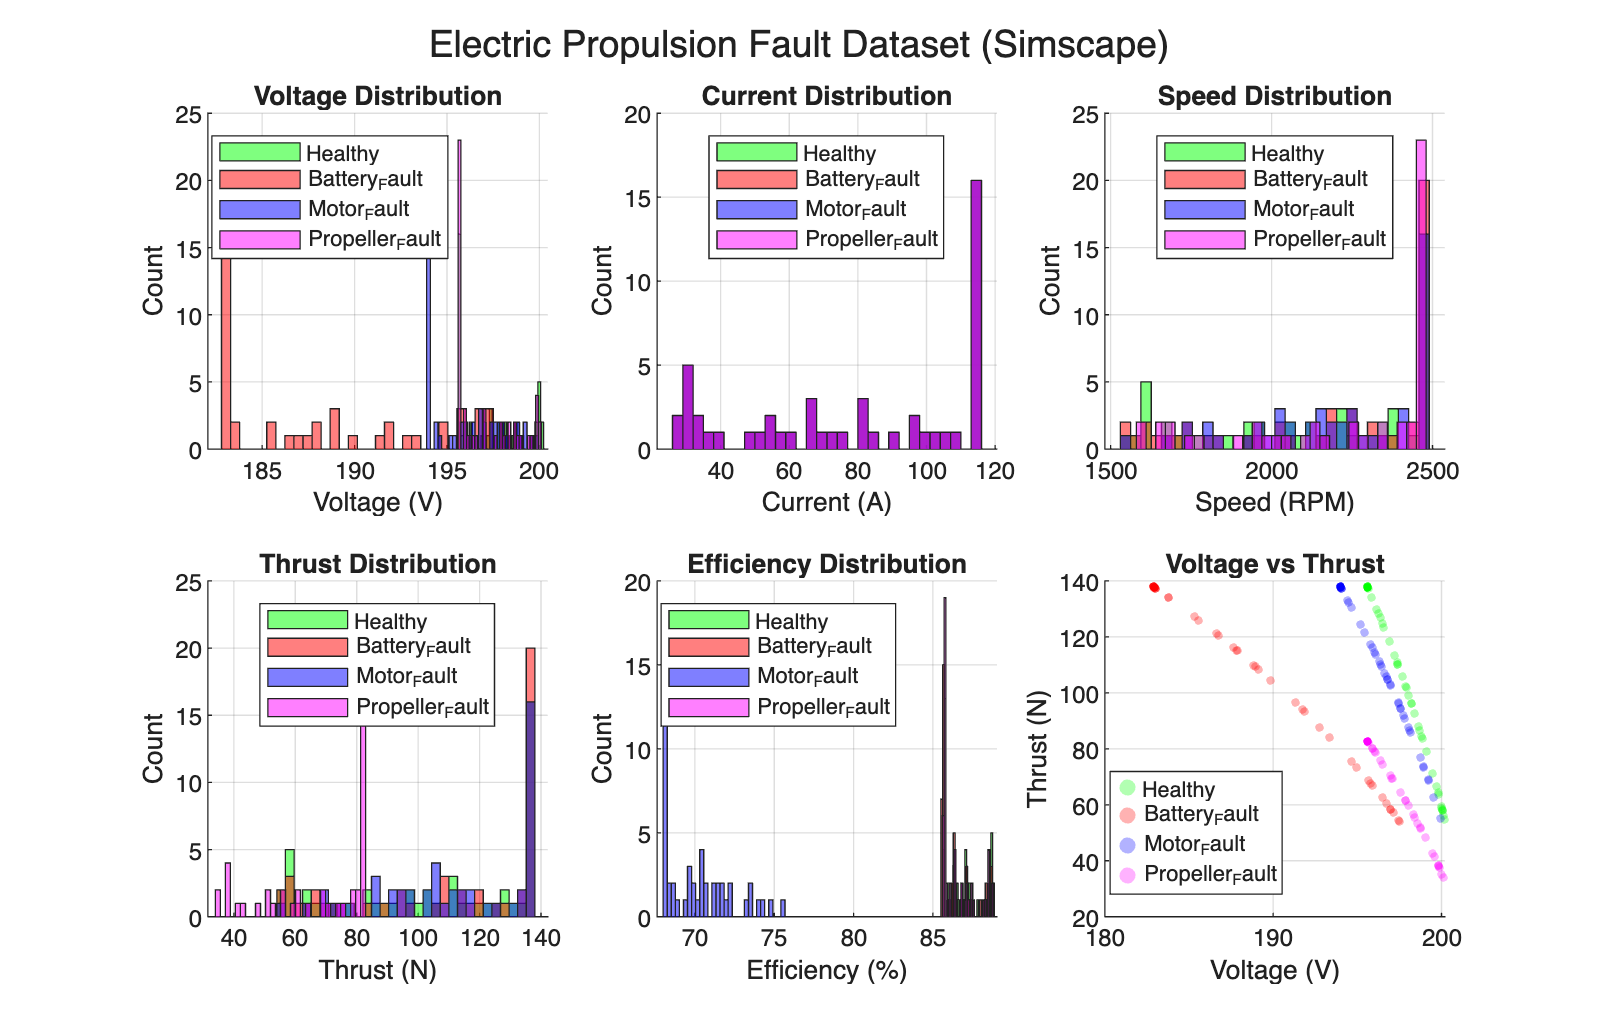

figure('Position', [100, 100, 1400, 900], 'Name', 'Fault Dataset Overview');

fault_colors = {'g', 'r', 'b', 'm'};
fault_names = {faults.name};

% 1. Voltage distribution
subplot(2, 3, 1);
hold on;
for f = 1:length(faults)
    idx = dataset == faults(f).label;
    histogram(dataset(idx, 3), 30, 'FaceColor', fault_colors{f}, 'FaceAlpha', 0.5);
end
xlabel('Voltage (V)');
ylabel('Count');
title('Voltage Distribution');
legend(fault_names, 'Location', 'best');
grid on;

% 2. Current distribution
subplot(2, 3, 2);
hold on;
for f = 1:length(faults)
    idx = dataset == faults(1).label;
    histogram(dataset(idx, 4), 30, 'FaceColor', fault_colors{f}, 'FaceAlpha', 0.5);
end
xlabel('Current (A)');
ylabel('Count');
title('Current Distribution');
legend(fault_names, 'Location', 'best');
grid on;

% 3. Speed distribution
subplot(2, 3, 3);
hold on;
for f = 1:length(faults)
    idx = dataset == faults(f).label;
    histogram(dataset(idx, 5), 30, 'FaceColor', fault_colors{f}, 'FaceAlpha', 0.5);
end
xlabel('Speed (RPM)');
ylabel('Count');
title('Speed Distribution');
legend(fault_names, 'Location', 'best');
grid on;

% 4. Thrust distribution
subplot(2, 3, 4);
hold on;
for f = 1:length(faults)
    idx = dataset == faults(f).label;
    histogram(dataset(idx, 7), 30, 'FaceColor', fault_colors{f}, 'FaceAlpha', 0.5);
end
xlabel('Thrust (N)');
ylabel('Count');
title('Thrust Distribution');
legend(fault_names, 'Location', 'best');
grid on;

% 5. Efficiency distribution
subplot(2, 3, 5);
hold on;
for f = 1:length(faults)
    idx = dataset == faults(f).label;
    data_f = dataset(idx, 10);
    data_f = data_f(data_f > 0 & data_f < 100);  % Filter valid efficiency
    if ~isempty(data_f)
        histogram(data_f, 30, 'FaceColor', fault_colors{f}, 'FaceAlpha', 0.5);
    end
end
xlabel('Efficiency (%)');
ylabel('Count');
title('Efficiency Distribution');
legend(fault_names, 'Location', 'best');
grid on;

% 6. Scatter: Voltage vs Thrust
subplot(2, 3, 6);
hold on;
for f = 1:length(faults)
    idx = dataset == faults(f).label;
    scatter(dataset(idx, 3), dataset(idx, 7), 10, fault_colors{f}, 'filled', 'MarkerFaceAlpha', 0.3);
end
xlabel('Voltage (V)');
ylabel('Thrust (N)');
title('Voltage vs Thrust');
legend(fault_names, 'Location', 'best');
grid on;

sgtitle('Electric Propulsion Fault Dataset (Simscape)', 'FontSize', 14);

% Save figure
saveas(gcf, 'simscape_fault_dataset_visualization.png');

fprintf('Visualization saved: simscape_fault_dataset_visualization.png\n');

Visualization saved: simscape_fault_dataset_visualization.png
